Barabasi-Albert demo: distance and diameter scaling

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_BA_DIAMETER_SCALING Empirical distance scaling for BA networks.
%
% For m >= 2, the asymptotic diameter of BA graphs is expected to scale like
% log n / log log n, though finite-size effects can be strong.


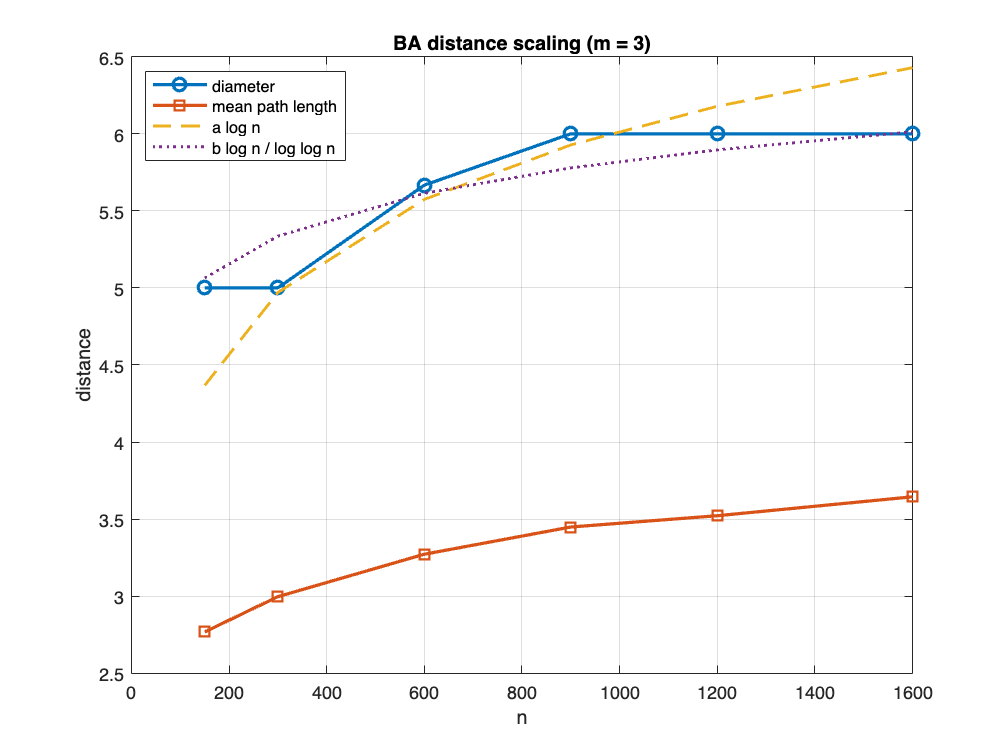

rng(4);

m0 = 5;
m = 3;
nVals = [150 300 600 900 1200 1600];
reps = 3;

meanPath = zeros(numel(nVals), reps);
diamVal = zeros(numel(nVals), reps);

for ii = 1:numel(nVals)
    n = nVals(ii);

    for r = 1:reps
        G = make_ba_graph(n, m0, m);
        [L, D] = path_length_stats(G, true);
        meanPath(ii, r) = L;
        diamVal(ii, r) = D;
    end
end

meanPathAvg = mean(meanPath, 2);
diamAvg = mean(diamVal, 2);

xLog = log(nVals(:));
xUltra = log(nVals(:)) ./ log(log(nVals(:)));

aLog = xLog \ diamAvg;
aUltra = xUltra \ diamAvg;

figure('Name', 'BA diameter scaling');
plot(nVals, diamAvg, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
plot(nVals, meanPathAvg, 's-', 'LineWidth', 1.8, 'MarkerSize', 7);
plot(nVals, aLog * xLog, '--', 'LineWidth', 1.6);
plot(nVals, aUltra * xUltra, ':', 'LineWidth', 1.6);
hold off;

xlabel('n');
ylabel('distance');
title(sprintf('BA distance scaling (m = %d)', m));
legend('diameter', 'mean path length', 'a log n', 'b log n / log log n', ...
    'Location', 'northwest');
grid on;


fprintf('\nBA diameter demo finished.\n');


BA diameter demo finished.


fprintf('Finite-size BA distances grow very slowly. Asymptotically the diameter is expected\n');

Finite-size BA distances grow very slowly. Asymptotically the diameter is expected


fprintf('to scale like log n / log log n for m >= 2, but small graphs are noisy.\n\n');

to scale like log n / log log n for m >= 2, but small graphs are noisy.

